# P2_plots

Use after running P1_main or loading the previous results in .mat file

FS = 'FontSize'; IN = 'Interpreter'; LT = 'Latex'; MS = 'MarkerSize'; 
LW = 'LineWidth'; FN = 'FontName'; TN = 'Times New Roman'; DN = 'DisplayName';
marker_set      = {'o';'d';'x';'s';'*';'_';'+';'^';'+';'.'};
color_sample    = (F_othercolor('Accent8',20)).^2;
color_set       = color_sample([1,10,14,5,20,3],:);
% F_color_check(color_set) %! only works in the command window

%! data for the plot
algs

algs = 1×4 の cell 配列
    {'greedyD'}    {'gradgreedyD'}    {'sdpD'}    {'crslcrD'}


% labels = algs; 
labels = {'greedyD','gradgreedyD','sdpD'}%,'crslcrD'}

labels = 1×3 の cell 配列
    {'greedyD'}    {'gradgreedyD'}    {'sdpD'}



%! lables on plot
% dnames = strrep(algs,'_','\_');
dnames = {'Pure gr.','Grad. gr.','SDP','Apprx. conv.'};
prob,ctime,obj

prob = フィールドをもつ struct :
        randseed: [1×1 struct]
            algs: {'greedyD'  'gradgreedyD'  'sdpD'  'crslcrD'}
               p: [10 10 10 10 10 10]
            pmax: 10
            pmin: 10
               r: [10 20 30 40 50 60]
            rmax: 60
            rmin: 10
    maxiteration: 5000
         amp_reg: 1.0000e-10
       data_type: 'SST'
        itr_data: 1
        itr_time: 1
        pathdata: '../data/SST/sst.wkmean.1990-present.nc'
               n: [44219 44219 44219 44219 44219 44219]
            nmax: 44219
            nmin: 44219
               m: 1727
        num_data: 1727
         num_cut: 1
         num_int: 1727
         usedind: {[1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]}
             dnm: 16
          ampeig: 9.9000e-01


ctime = フィールドをもつ struct :
        greedyD: [1.9755e+01 6.3913e+01 1.5192e+02 2.6482e+02 4.4245e+02 6.1113e+02]
    gradgreedyD: [2.3642e-02 2.9028e-02 4.7839e-02 6.3373e-02 7.5601e-02 1.0242e-01]
           sdpD: [3.9194e+00 9.0360e+00 2.1074e+01 3.9691e+01 7.0771e+01 1.1137e+02]
        crslcrD: [9.6339e+01 2.6737e+02 6.6066e+02 1.5862e+03 2.7933e+03 3.6576e+03]
        randomD: [3.0879e-02 1.7599e-03 3.2218e-03 5.4111e-03 8.3657e-03 1.1560e-02]


obj = フィールドをもつ struct :
        greedyD: [6.3973e-14 4.0707e-39 6.9695e-70 1.5076e-107 4.5625e-150 0]
    gradgreedyD: [8.0735e-14 3.6355e-39 2.1338e-72 1.6913e-108 9.7536e-151 2.7369e-207]
           sdpD: [8.3349e-14 3.0052e-39 3.5348e-71 1.5241e-110 2.6418e-153 1.3920e-208]
        crslcrD: [8.6993e-14 3.0052e-39 9.1571e-73 9.0321e-110 4.2935e-153 1.3920e-208]
        randomD: [3.7638e-23 3.3409e-56 1.0944e-96 8.2723e-140 9.5805e-191 3.8051e-246]
    crslcrD_rlx: [9.8340e-14 2.3061e-36 2.8373e-60 4.4972e-85 1.0188e-109 3.6240e-135]
       sdpD_rlx: [1.0032e-13 1.9021e-36 1.9682e-60 2.4129e-85 3.6616e-110 1.6654e-135]


r = prob.r; p = prob.p; n = prob.n;

% %{
xtmp    = r; xlblttl = 'Rank of system; \itr';
XT1     = [r(1),r(fix(end/2+1/2)),r(end)];
XTL     = num2str([r(1),r(fix(end/2+1/2)),r(end)]');
XMT     = 'on'; LgL = 'southwest';
YLM1    = [1e-4 5e4];
YLM2    = [9e-4 2.1e0];
stmp    = 'r'; sorder = [2,3,3];
YT2     = [1e-3 1e-2 1.0e-1 1e0]

YT2 =    1.0000e-03   1.0000e-02   1.0000e-01   1.0000e+00


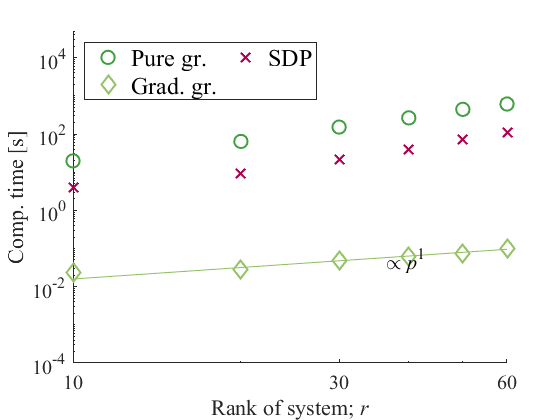

stmp    = 'p'; sorder = [1,2,4];
%}

%{
xtmp = p; xlblttl = 'No. selected sensors; \itp';
XT1     = [p(1),p(fix(end/2+1/2)),p(end)];
XTL     = num2str([p(1),p(fix(end/2+1/2)),p(end)]');
XMT     = 'on'; LgL = 'southeast';
YLM1    = [1e-4 5e4];

YT2     = [1e-4 1e-3 1e-2 1.0e-1 1e0]
YLM2    = [1e-1 2e0];% [-Inf, Inf];% 
stmp    = 'p'; sorder = [1,2,4];
%}

%{
xtmp    = n; xlblttl = 'No. of sensor candidates; \itn';
XT1     = n;
bas     = repmat('2^{',width(n),1);pow = num2str(log2(n)');rbr = repmat('}',width(n),1);XTL = string([bas,pow,rbr]);
XMT     = 'off'; LgL = 'east';
YLM1    = [1e-4 3e4];
YT2     = [1e-4 1e-3 1e-2 1.0e-1 1e0]
YLM2    = [1e-4 3e0];
stmp    = 'n'; sorder = [1,2,4];
%}

xc = xtmp(fix(end/2+1));

t = figure();
h = struct();
ax1 = axes(t);
ltmp = [];
hold on
for j = 1:size(labels,2)
    algtmp      = labels{j};
    marker_tmp  = char(marker_set(strcmp(algtmp,labels)));
    color_tmp   = color_set(strcmp(algtmp,labels),:);
    for k = 1%:size(ctime.(algtmp),3)
        ytmp = mean(ctime.(algtmp)(:,1:size(xtmp,2),k),1,'omitnan');
        h1.([(algtmp),'_',num2str(k)]) = plot(ax1,xtmp,ytmp,'-x','Marker',marker_tmp,DN,[dnames{j}],'Color',color_tmp);          
        h1.([(algtmp),'_',num2str(k)]).LineStyle = 'none';    
        h1.([(algtmp),'_',num2str(k)]).MarkerSize = 10;
        h1.([(algtmp),'_',num2str(k)]).LineWidth = 1.5;
    end
    ltmp = [ltmp,h1.([(algtmp),'_',num2str(k)])]; 
end

strtmp = string(sprintf('{\\it%s}^{%d}', stmp,sorder(1)));
F_linear_line(t,h1.gradgreedyD_1,sorder(1),[strtmp{:}]);

hold off
ax1.XScale = 'log'; ax1.YScale = 'log';
hold off;
ax1.Box = 'off';
ax1.Color = 'none';
set(ax1,FS,15,FN,'Times New Roman');
ax1.XTick = XT1; ax1.XTickLabel = XTL; ax1.XMinorTick = XMT;
ax1.YTick = [1e-4 1e-2 1e0 1e2 1e4];
ylabel(ax1,'Comp. time [s]');
xlabel(ax1,xlblttl);
legend(ltmp,FS,18,'Color','none','NumColumns',2,"Location",'NorthWest')
ax1.YLim = YLM1;  

filen = [pathwork,'ctime_',prob.data_type,'_',dates.end]

filen = '../work/SST/ctime_SST_0521,235412'

% F_save_fig(filen)

t = figure();
ax2 = axes(t);
ltmp = [];
hold on
dnmtmp = obj.greedyD;
for j = 1:size(labels,2)
    algtmp = labels{j}
    marker_tmp  = char(marker_set(strcmp(algtmp,labels)));
    color_tmp   = color_set(strcmp(algtmp,labels),:);
    for k = 1%:size(ctime.(algtmp),3)
        objtmp = obj.(algtmp)(:,:,k)./ dnmtmp;
        ytmp = mean(objtmp,1,'omitnan');
            h2.([(algtmp),'_',num2str(k)]) = plot(ax2,xtmp,ytmp,'-x','Marker',marker_tmp,DN,[dnames{j}],'Color',color_tmp);
        h2.([(algtmp),'_',num2str(k)]).LineStyle = 'none';    
        h2.([(algtmp),'_',num2str(k)]).MarkerSize = 10;
        h2.([(algtmp),'_',num2str(k)]).LineWidth = 1.5;
    end
    ltmp = [ltmp,h2.([(algtmp),'_',num2str(k)])]; 
end

algtmp = 'greedyD'

algtmp = 'gradgreedyD'

algtmp = 'sdpD'

hold off
ax2.XScale = 'log'; ax2.YScale = 'log';
ax2.Box = 'off';
ax2.Color = 'none';
set(ax2,FS,15,FN,'Times New Roman');
ax2.XTick = XT1; ax2.XTickLabel = XTL; ax2.XMinorTick = XMT;
ax2.YTick = YT2;
xlabel(ax2,xlblttl);
ylabel(ax2,{'Objective value ratio'});
legend(ltmp,'Location',LgL,FS,18,'Color','none')
ax2.YLim = YLM2;  
filen = [pathwork,'obj_',prob.data_type,'_',dates.end]

filen = '../work/SST/obj_SST_0521,235412'

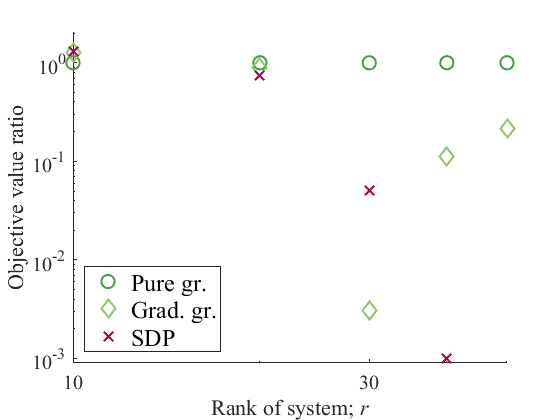

saved to --> ../work/SST/obj_SST_0521,235412


F_save_fig(filen)

t = tiledlayout(2,1,'TileSpacing','compact');
filen = [pathwork,'ctimeobj_',prob.data_type,'_',dates.end]
h = struct();
ax1 = axes(t);
ax1.Layout.Tile = 1;
hold on
ltmp = [];
for j = 1:size(labels,2)
    algtmp      = labels{j};
    marker_tmp  = char(marker_set(strcmp(algtmp,labels)));
    color_tmp   = color_set(strcmp(algtmp,labels),:);
    for k = 1%:size(ctime.(algtmp),3)
        ytmp = mean(ctime.(algtmp)(:,1:size(xtmp,2),k),1,'omitnan');
        h.([(algtmp),'_',num2str(k)]) = plot(ax1,xtmp,ytmp,'-x','Marker',marker_tmp,DN,[dnames{j},' ',num2str(k)],'Color',color_tmp);         
        h.([(algtmp),'_',num2str(k)]).LineStyle = 'none';    
        h.([(algtmp),'_',num2str(k)]).MarkerSize = 10;
        h.([(algtmp),'_',num2str(k)]).LineWidth = 1.5;
    end
    ltmp = [ltmp,h.([(algtmp),'_',num2str(k)])]; 
end
hold off
ax1.XScale = 'log'; ax1.YScale = 'log';
hold off;
ax1.Box = 'off';
ax1.XMinorTick = 'off';
ax1.XTick = XT1; ax1.XTickLabel = [];
ax1.Color = 'none';
set(ax1,FS,15,FN,'Times New Roman');
ax1.XTickLabel = [];
ax1.YTick = [1e-2 1e0 1e2];
ylabel(ax1,'Comp. time [s]');

ax2 = axes(t);
ax2.Layout.Tile = 2;
hold on
dnmtmp =obj.greedyD;
ltmp = [];
for j = 1:size(labels,2)
    algtmp = labels{j}
    marker_tmp  = char(marker_set(strcmp(algtmp,labels)));
    color_tmp   = color_set(strcmp(algtmp,labels),:);
    for k = 1%:size(ctime.(algtmp),3)
        objtmp = obj.(algtmp)(:,:,k)./ dnmtmp;
        ytmp = mean(objtmp,1,'omitnan');
            h.([(algtmp),'_',num2str(k)]) = plot(ax2,xtmp,ytmp,'-x',...
                'Marker',marker_tmp,DN,[dnames{j}],'Color',color_tmp);
        h.([(algtmp),'_',num2str(k)]).LineStyle = 'none';    
        h.([(algtmp),'_',num2str(k)]).MarkerSize = 10;
        h.([(algtmp),'_',num2str(k)]).LineWidth = 1.5;
    end
    ltmp = [ltmp,h.([(algtmp),'_',num2str(k)])]; 
end
hold off
ax2.XScale = 'log'; ax2.YScale = 'log';
ax2.Box = 'off';
ax2.Color = 'none';
set(ax2,FS,15,FN,'Times New Roman');
ax2.XTick = XT1; ax2.XTickLabel = XTL; ax2.XMinorTick = XMT;
ax2.XMinorTick = 'off';
xlabel(ax2,xlblttl);
ylabel(ax2,{'Objective value ratio'});
% ax2.YLim = [4.0e-1 1.1e0];  legend(FS,18,'Color','none','Location','southwest','NumColumns',2)
legend(ltmp,'Location',LgL,FS,18,'Color','none')